# Try9 version1 （不规则图形，高斯迭代，矩阵法，迭代次数上限）

基于 版本try6

看起来似乎可行，用echelon和改变cond d arret 实现。使用echelon因为while中套for耗时久。

热方程仍有疑问

## Paramètre


x=419;   %longueur en x
y=150;   %longueur en y
h=1;  %pas
phi_k=-1; %carac thermique -phi/k
% si cette valeur positive, creux
m=0:h:x;
n=0:h:y;
T=zeros(length(n),length(m))

T =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% Echelon=ones(length(n),length(m));


## Matrice Muttin

## M


M1=[tril(ones(50)) fliplr(tril(ones(50)))  ];
M2=[ones(30,20) triu(ones(30)) fliplr(triu(ones(30))) ones(30,20)];
M3=[ones(71,20) zeros(71,60) ones(71,20)];
M=[M1;M2;M3];
% mesh(M)


## U


rond1= ~circle(10,10,10,0,10)

rond1 = 10×10 logical array
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   0   0   0   0
   1   1   1   1   1   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   0


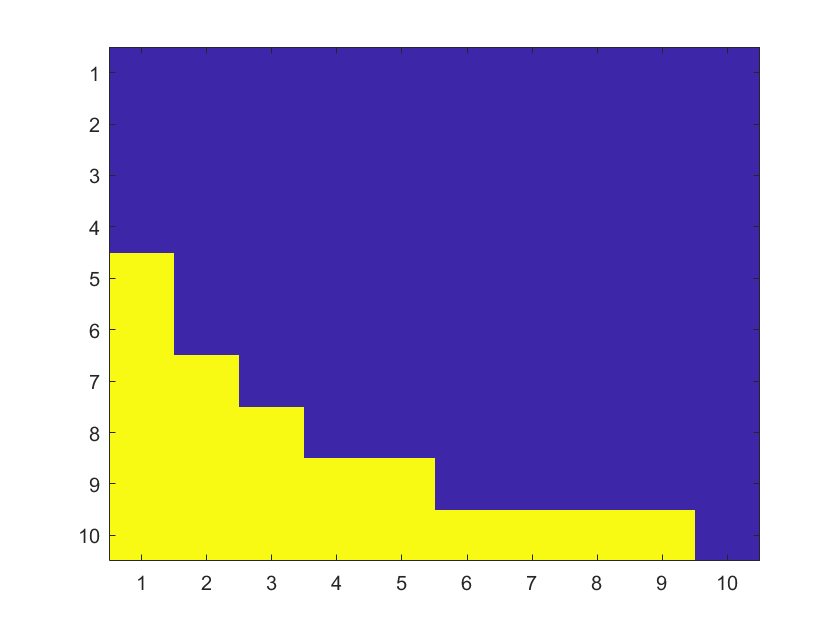

imagesc(rond1)

rond2=fliplr(rond1);
U1=[ones(55,20) zeros(55,30) ones(55,20)  ];
U2=[ones(10,20) rond1 zeros(10,10) rond2 ones(10,20)  ];
U3=[~rond1 ones(10,50) ~rond2];
U=[zeros(76,70);U1;U2;U3];
% mesh(U)


## tt


t1=[zeros(71,20) ones(71,20) zeros(71,30)];
t2=ones(20,70);
t3_1=[zeros(30,20) ones(30,20) zeros(30,30)];
t3_2=[zeros(10,20) ones(10,20) zeros(10,20) ones(10)]

t3_2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

t4=[zeros(10,20) ones(10,20) rond1 rond2 ones(10,10)];
t5=[zeros(10,20) ~rond1 ones(10,30) ~rond2];
t=[t1;t2;t3_1;t3_2;t4;t5];
tt=[t t];
% mesh(tt)


## i


i1=zeros(46,20);
i2=[flip(~rond1) flip(~rond2)];
i3=flip(i2);
i4=[rond2 rond1];
i5=ones(75,20);
i=[i1; i2;i3;i4;i5]

i =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    

i=[zeros(151,10) i zeros(151,10)];
% mesh(i)


## n

n1=zeros(81,70);
n2=[ones(10,20) flip(~rond1) ones(10,30) flip(~rond2)];
n3=[ones(10,20) flip(rond1) zeros(10,10) flip(rond2) ones(10,20)];
n4=[ones(50,20) zeros(50,30) ones(50,20)];
n=[ n1;n2;n3;n4];


## Muttin

Muttin=[M U tt i n]

Muttin =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     0     0     0     0     0     0     0     0     0     0    

## Condition frontière


T(1,:)=100;
T(:,1)=50;
T(length(n),:)=-20;
T(:,length(m))=-10;
% T(25:50,1)=100;
% Echelon(1:20,75:101)=0;
T=T.*Muttin;
T1=T;
% [xq,yq] = meshgrid(m, n)
% xq
% yq
% mesh(xq,yq,T1)

## Gausse-Seidel

e=1; count=0; temp=0;
while count<=1000
    count=count+1;
    T=T.*Muttin;
    temp=T(round(length(n)/2),round(length(m)/2));
    T1(2:length(n)-1,2:length(m)-1)=(T(2:length(n)-1,1:length(m)-2) ...%West
        +T(2:length(n)-1,3:length(m)) ...%East
        +T(1:length(n)-2,2:length(m)-1) ...%North
        +T(3:length(n),2:length(m)-1))/4-(h^2*phi_k)/4; %South
    
%     e=abs((T1(round(length(n)/2),round(length(m)/2))-temp)/T1(round(length(n)/2),round(length(m)/2)));
    T=T1;
end
count

count = 1001

## graphe

for i=1:size(T,1)
    for j=1:size(T,2)
        if T(i,j)==0
            T(i,j)=nan;
        end
    end
end
T

T =    50.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.0000   20.2644    8.6472    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0

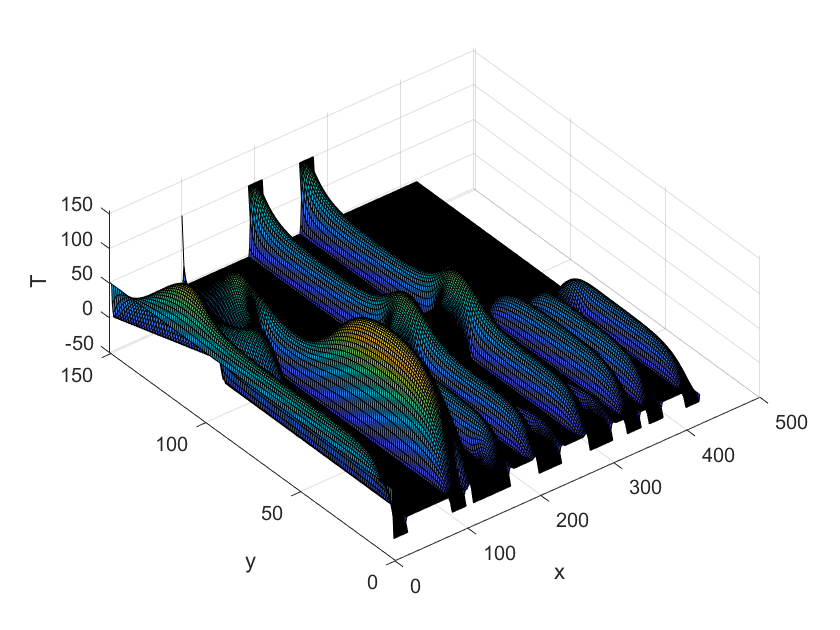

mesh(flip(T))
xlabel('x')
ylabel('y')
zlabel('T')

## fct interne

function[res] = circle(xlength,ylength,xpos,ypos,radius)
[x,y] = meshgrid(1:xlength, 1:ylength);
res = (x - xpos).^2 + (y - ypos).^2 <= radius^2;
% res=1*res;
% mesh(res)
% xlabel('x')
% ylabel('y')
end